#  Geometric Integration of Quaternions

cf. Andrle, Michael S., & Crassidis, John L. “Geometric Integration of Quaternions.” Journal of Guidance, Control, and Dynamics, vol. 36, no. 6, 2013, pp. 1762-67.

clc
clear


format long

## parameters and initial condition

MOI = diag([200 200 100]); % Moment of inertia

dt = 1;
tspan = 0:dt:4*60*60;
qIni = [0, 0, 0, 1];
wIni = [0.05, 0, 0.01]

wIni =    0.050000000000000                   0   0.010000000000000


xIni = [qIni, wIni];

## 4th Runge–Kutta method

xRK = ode4(@(t,x)eulerEom(t,x,MOI), tspan, xIni);


## adaptive ODE solver

[~, xAdaptive] = ode45(@(t,x)eulerEom(t,x,MOI), tspan, xIni);


## Crouch–Grossman method

### three-stage CG3 mixed-scheme

[qOut, wOut] = qGI(4, tspan, qIni, wIni, 3, MOI);

% nStage = 3; % n-stage CG method
% [a, b, c] = butcherTable(3, 'CG');
% 
% k = zeros(nStage, 3);
% K = zeros(4,4,nStage);
% w = zeros(nStage,3); %
% 
% w(1,:) = wIni; % intermidiate angular rate
% wOut = zeros(length(tspan),3); % nx3
% wOut(1,:) = w(1,:);
% qOut = zeros(length(tspan), 4); % nx4
% qOut(1,:) = qIni;
% 
% for kk = 1:length(tspan)-1
% 
%     % when i = 1
%     w(1,:) = wOut(kk,:);
%     tmpk = -MOI^(-1) * cross(w(1,:)', MOI * w(1,:)');
%     k(1,:) = tmpk';
%     K(:,:,1) = 0.5 * qMultMat(4, 1,[w(1,:), 0]);
% 
%     for i = 2:nStage    % for each stage  
%         tmpw = w(1,:);
%         for j = 1:i-1
%             tmpw = tmpw + a(i,j) * dt .* k(j,:);
%         end
%         w(i,:) = tmpw;
% 
%         tmp = -MOI^(-1) * cross(w(i,:)', MOI * w(i,:)');
%         k(i,:) = tmp';
%         K(:,:,i) = 0.5 * qMultMat(4, 1,[w(i,:), 0]); % 4x4xs
%     end
% 
%     tmp = zeros(1,3);
%     for i =1:nStage
%         tmp = tmp + dt .* b(i) .* k(i,:);
%     end
%     wOut(kk+1,:) = wOut(kk,:) + tmp;
% 
%     tmp = qOut(kk,:)';
%     for i = 1:nStage
%         tmp = expm(dt .* b(i) .* K(:,:,i)) * tmp;
%     end
% 
%     qOut(kk+1,:) = tmp';
% 
% end


## five-stage CG4

[qOutCG4, wOutCG4] = qGI(4, tspan, qIni, wIni, 4, MOI);

% nStage = 5; % n-stage CG method
% [a, b, c] = butcherTable(4, 'CG')
% 
% k = zeros(nStage, 3);
% K = zeros(4,4,nStage);
% w = zeros(nStage,3); %
% 
% w(1,:) = wIni; % intermidiate angular rate
% wOutCG4 = zeros(length(tspan),3); % nx3
% wOutCG4(1,:) = w(1,:);
% qOutCG4 = zeros(length(tspan), 4); % nx4
% qOutCG4(1,:) = qIni;
% 
% for kk = 1:length(tspan)-1
% 
%     % for each stage
%     w(1,:) = wOutCG4(kk,:);
%     tmpk = -MOI^(-1) * cross(w(1,:)', MOI * w(1,:)');
%     k(1,:) = tmpk';
%     K(:,:,1) = 0.5 * qMultMat(4, 1,[w(1,:), 0]);
% 
%     for i = 1:nStage  
%         tmpw = w(1,:);
%         for j = 1:i-1  % s = 1のときは入らない
%             tmpw = tmpw + a(i,j) * dt .* k(j,:);
%         end
%         w(i,:) = tmpw;
% 
%         tmp = -MOI^(-1) * cross(w(i,:)', MOI * w(i,:)');
%         k(i,:) = tmp';
%         K(:,:,i) = 0.5 * qMultMat(4, 1, [w(i,:), 0]); % 4x4xs
%     end
% 
%     tmp = zeros(1,3);
%     for i =1:nStage
%         tmp = tmp + dt .* b(i) .* k(i,:);
%     end
%     wOutCG4(kk+1,:) = wOutCG4(kk,:) + tmp;
% 
%     tmp = qOutCG4(kk,:)';
%     for i = 1:nStage
%         tmp = expm(dt .* b(i) .* K(:,:,i)) * tmp;
%     end
% 
%     qOutCG4(kk+1,:) = tmp';
% 
% end

## analytical solutions (closed form solution, CS)

[qCS, wCS] = axiQsol(tspan, qIni, wIni, MOI);


## data handling and comparison

qAd = xAdaptive(:,1:4);
wAd = xAdaptive(:,5:7);
qRK = xRK(:,1:4);
wRK = xRK(:,5:7);

th = tspan./60/60;

% quaternion norm
figure
plot(th, log10(1 - vecnorm(qRK,2,2).^2)); hold on
plot(th, log10(1 - vecnorm(qOut,2,2).^2),'o')

plot(th, log10(1 - vecnorm(qOutCG4,2,2).^2),'x')

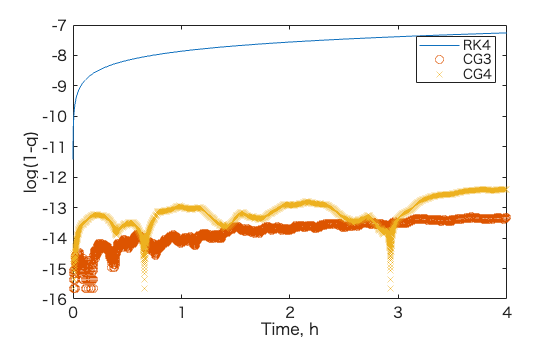

xlabel('Time, h')
ylabel('log(1-q)')
legend('RK4', 'CG3', 'CG4')

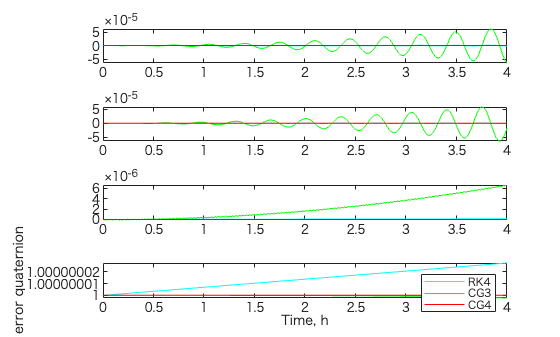


% quaternion, 解析解を真値として，，，
qErrRK = qErr(4, qCS, qRK);
qErrCG3 = qErr(4, qCS, qOut);
qErrCG4 = qErr(4, qCS, qOutCG4);

figure
tiledlayout(4,1)
for i = 1:4
    nexttile
    plot(th, qErrRK(:,i), 'c', th, qErrCG3(:,i), 'g', th, qErrCG4(:,i), 'r')
end
xlabel('Time, h')
ylabel('error quaternion')
legend('RK4', 'CG3', 'CG4')

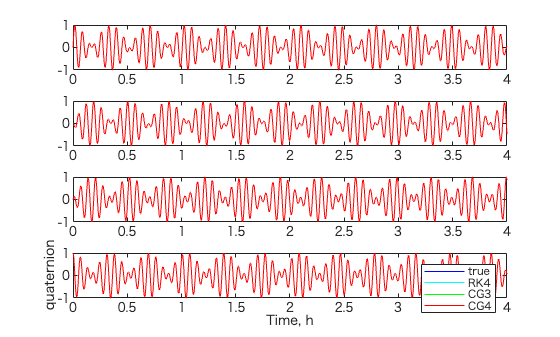


figure
tiledlayout(4,1)
for i = 1:4
    nexttile
    plot(th, qCS(:,i), 'b', th, qRK(:,i), 'c', th, qOut(:,i), 'g', th, qOutCG4(:,i), 'r')
end
xlabel('Time, h')
ylabel('quaternion')
legend('true', 'RK4', 'CG3', 'CG4')

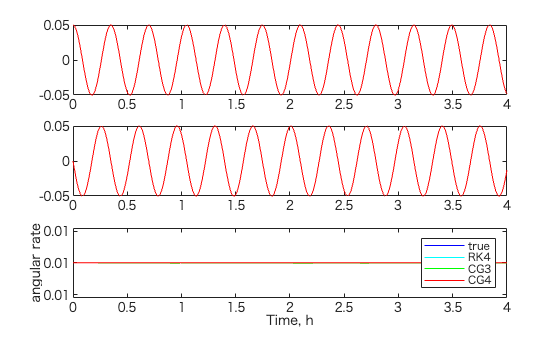


figure
tiledlayout(3,1)
for i = 1:3
    nexttile
    plot(th, wCS(:,i), 'b', th, wRK(:,i), 'c', th, wOut(:,i), 'g', th, wOutCG4(:,i), 'r')
end
xlabel('Time, h')
ylabel('angular rate')
legend('true', 'RK4', 'CG3', 'CG4')